MATLAB 3주차 과제 25012601 양가인

1.

fprintf("1번 문제:\n");

1번 문제:


A1 = [1 4 2;
    2 4 100;
    7 9 7;
    3 pi 42]

A1 =     1.0000    4.0000    2.0000
    2.0000    4.0000  100.0000
    7.0000    9.0000    7.0000
    3.0000    3.1416   42.0000



B1 = log(A1)

B1 =          0    1.3863    0.6931
    0.6931    1.3863    4.6052
    1.9459    2.1972    1.9459
    1.0986    1.1447    3.7377


(a) B의 두 번째 행을 선택하라.

a1 = B1(2,:)

a1 =     0.6931    1.3863    4.6052


(b) B의 두 번째 행의 합을 구하라.

b1 = sum(a1)

b1 = 6.6846

(c) B의 두 번째 열과 A의 첫 번째 열의 원소별 곱을 구하라.

c1 = B1(:,2).*A1(:,1)

c1 =     1.3863
    2.7726
   15.3806
    3.4342


(d) 위 결과 벡터의 최대값을 구하라.

d1 = max(c1)

d1 = 15.3806

(e) 원소별 나눗셈을 사용하여 A의 첫 번째 행을 B의 세 번째 열의 처음 세 원소로 나누고, 결과 벡터의 합을 구하라.

e1 = sum(A1(1,:) ./ B1(1:3,3)')

e1 = 3.3391

2.

fprintf("2번 문제:\n");

2번 문제:


v0 = 50; % m/s
A2 = 50 * pi / 180; % rad
g = 9.81; % m/s^2

(a) 충돌시간 t_hit와 최고 높이 y_max를 구하라.

t_hit = 2* v0*sin(A2)/g

t_hit = 7.8088


y_maxt = v0*sin(A2)/g;
y_max = (v0*sin(A2))*y_maxt - g*(y_maxt^2)/2

y_max = 74.7737

(b) (0 <= t <= t_hit 구간에서 x대 y 그래프를 그려라.

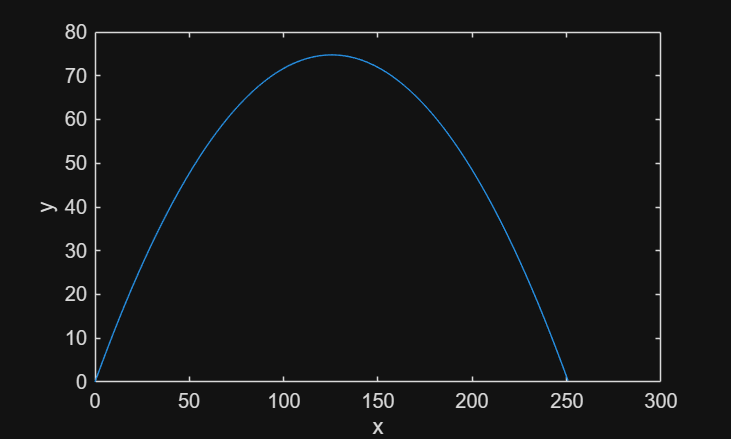

t = 0:0.1:t_hit;
x2 = t.*(v0*cos(A2));
y2 = (v0*sin(A2).*t - (1/2)*g.*(t.^2));
plot(x2, y2)
xlabel('x');
ylabel('y');

3.

fprintf("3번 문제:\n");

3번 문제:


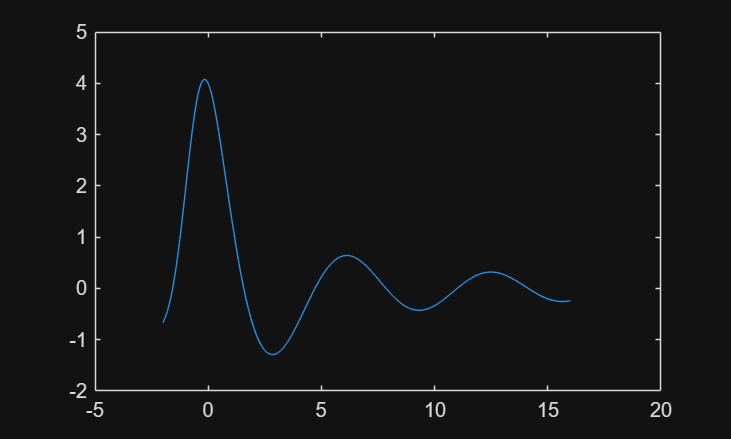

x3 = -2:0.1:16;
y3 = 4*cos(x3)./(x3 + exp(-0.75.*x3));
plot(x3, y3)

4.

fprintf("4번 문제:\n");

4번 문제:


(a) 5x3 소비 행렬을 생성하라.

a4 = {1, 300, [5, 4, 6];
    2, 550, [3, 2, 4];
    3, 400, [6, 5, 3];
    4, 250, [3, 5, 4];
    5, 500, [2, 4, 3]};
a4

a4 = 5×3 cell 배열
    {[1]}    {[300]}    {[5 4 6]}
    {[2]}    {[550]}    {[3 2 4]}
    {[3]}    {[400]}    {[6 5 3]}
    {[4]}    {[250]}    {[3 5 4]}
    {[5]}    {[500]}    {[2 4 3]}


(b) 각 달의 총 소비량을 구하라.

b4 = zeros(1, 3);
for i=1:3
    for j=1:5
        b4(1, i) = b4(1, i) + a4{j, 2} * a4{j, 3}(i);
    end
end
b4

b4 =         7300        7550        7700


(c) 3개월 동안 각 재료별 총 소비량을 구하라.

c4 = zeros(5, 1);
for i = 1:5
    c4(i, 1) = a4{i, 2} * sum(a4{i, 3});
end
c4

c4 =         4500
        4950
        5600
        3000
        4500


5.

fprintf("5번 문제:\n");

5번 문제:


(a) 다음 다항식의 곱을 구하라.

a5 = conv([5, 0, -3, 7, 10], [4 -7 9 2])

a5 =     20   -35    33    59   -36   -13   104    20


(b) 다음 식의 몫과 나머지를 구하라.

[bq, br] = deconv([5 -7 2 8], [6 3 -2])

bq =     0.8333   -1.5833


br =          0         0    8.4167    4.8333


(c) x = 5에서 다음 식의 값을 계산하라.

[cq, cr] = deconv([36 -8 0 2], [36 -5 4 -3]);
c5 = polyval(cq, 5) + (polyval(cr, 5) / polyval([36 -5 4 -3], 5))

c5 = 0.9795

6.

fprintf("6번 문제:\n");

6번 문제:


(a) 위 표의 정보를 갖는 구조체 배열을 생성하라.

bridge(1).loc = 'Smith St.';%위치
bridge(1).w = 80;%최대 하중
bridge(1).y1 = 1928;%건설연도
bridge(1).y2 = 2025;%유지기한

bridge(2).loc = 'Hope Ave.';
bridge(2).w = 90;
bridge(2).y1 = 1950;
bridge(2).y2 = 2027;

bridge(3).loc = 'Clark St.';
bridge(3).w = 85;
bridge(3).y1 = 1933;
bridge(3).y2 = 2024;

bridge(4).loc = 'North Rd.';
bridge(4).w = 100;
bridge(4).y1 = 1960;
bridge(4).y2 = 2023;

bridge

bridge = 다음 필드를 포함한 1×4 struct 배열:
    loc
    w
    y1
    y2


(b) 문제 (a)에서 생성한 구조체 배열 요소 중  Clark St. 다리의 유지 기한을 2026년으로 수정하라.

bridge(3). y2 = 2026

bridge = 다음 필드를 포함한 1×4 struct 배열:
    loc
    w
    y1
    y2


(c) 다음 다리 정보를 구조체 배열에 추가하라.

bridge(5).loc = 'Shore Rd.';
bridge(5).w = 85;
bridge(5).y1 = 1997;
bridge(5).y2 = 2022

bridge = 다음 필드를 포함한 1×5 struct 배열:
    loc
    w
    y1
    y2
